# Example: COVID-2019 data for Italian Regions

The data is taken from official Italian government figures [1]. This mlx. file was proposed by matteo Secli [2] but I did some modifications to it.

[1] [https://github.com/pcm-dpc/COVID-19](https://github.com/pcm-dpc/COVID-19)

[2] [https://github.com/matteosecli](https://github.com/matteosecli)

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;

% Download the data from ref [1] and read them with the function
% getDataCOVID_ITA
tableCOVIDItaly = getDataCOVID_ITA();

time = unique(datetime(datestr(datenum(tableCOVIDItaly.Date,'yyyy-mm-DDThh:MM:ss'))));
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 18-Apr-2020 17:00:00



% Add regions and populations here to generate more plots. Eurostat 2018
% data.
Regions     = {'Lombardia', 'Veneto', 'Emilia-Romagna', 'Piemonte'};
Populations = [10.040e6   , 4.905e6 , 4.453e6         , 4.376e6   ];

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.5; % rate at which infectious people enter in quarantine
lambda_guess = [0.1,0.05]; % recovery rate
kappa_guess = [0.02,0.05]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    Q_guess,...
    lambda_guess,...
    kappa_guess];

## Iterative application of fit_SEIQRDP

Active cases = Confirmed-Deaths-Recovered (database) = Quarantined (SEIQRDP model)

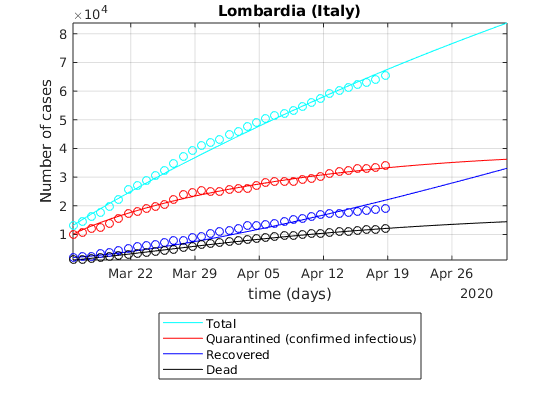

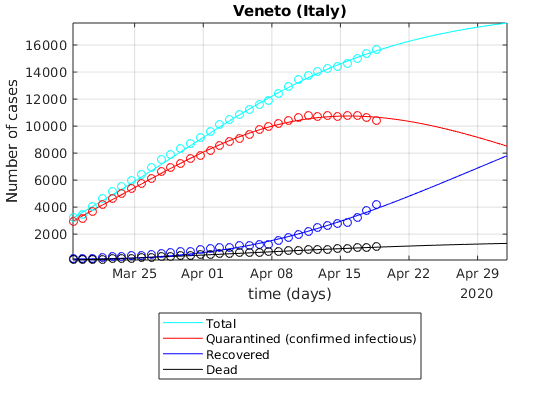

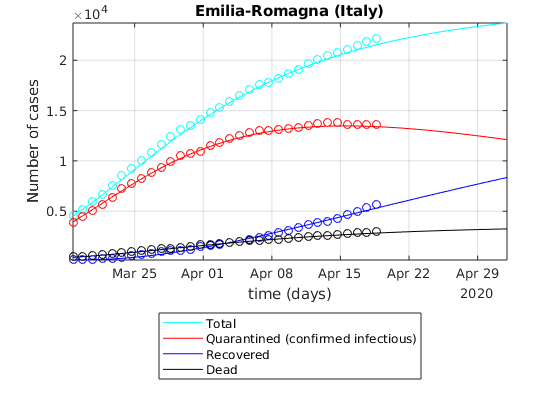

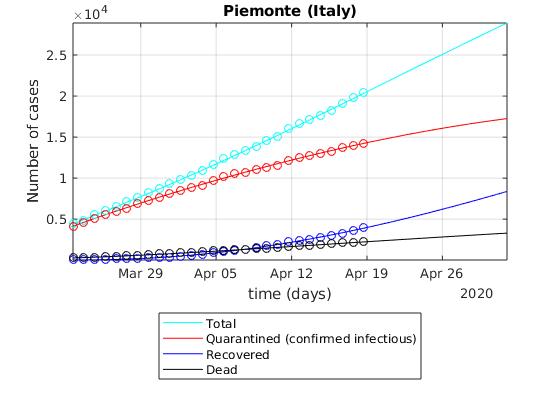




for regionIdx=1:numel(Regions)
    
    % Region definitions
    regionName = Regions{regionIdx};
    Npop       = Populations(regionIdx); % population
    
    try
        indLocation = find(contains(tableCOVIDItaly.RegionName,regionName)==1);
    catch exception
        searchLoc = strfind(tableCOVIDItaly.RegionName,regionName);
        indLocation = find(~cellfun(@isempty,searchLoc)) ; 
    end
    
    % Remove the ";" at the end of the line below to show regional data
    tableCOVIDItaly(indLocation,[1,7:end]);
    
    Recovered   = tableCOVIDItaly.Recovered  (indLocation)';
    Deaths      = tableCOVIDItaly.Deaths     (indLocation)';
    Confirmed   = tableCOVIDItaly.Confirmed  (indLocation)';
    Quarantined = tableCOVIDItaly.Quarantined(indLocation)';
    time        = tableCOVIDItaly.Date       (indLocation)';
    time = unique(datetime(datestr(datenum(tableCOVIDItaly.Date,'yyyy-mm-DDThh:MM:ss'))));
    
    
    
    % If the number of confirmed Confirmed cases is small, it is difficult to know whether
    % the quarantine has been rigorously applied or not. In addition, this
    % suggests that the number of infectious is much larger than the number of
    % confirmed cases
    minNum= round(0.2*max(Confirmed));
    Recovered  (Confirmed<=minNum)=[];
    Deaths     (Confirmed<=minNum)=[];
    time       (Confirmed<=minNum)=[];
    Quarantined(Confirmed<=minNum)=[];
    Confirmed  (Confirmed<=minNum)=[];
    
    %% To simulate the cases after fitting
    dt = 1/24; % time step
    time1 = time(1):dt:datetime(datestr(floor(datenum(now))+datenum(14)));
    N = numel(time1);
    t = [0:N-1].*dt;
    
    
    % Initial conditions
    E0 = Confirmed  (1); % Initial number of exposed cases. Unknown but unlikely to be zero.
    I0 = Confirmed  (1); % Initial number of infectious cases. Unknown but unlikely to be zero.
    Q0 = Quarantined(1);
    R0 = Recovered  (1);
    D0 = Deaths     (1)*0.9;
    
    [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
        fit_SEIQRDP(Quarantined,Recovered,Deaths,Npop,E0,I0,time,guess,'Display','off','dt',0.1);
    
    % Simulate the epidemy outbreak based on the fitted parameters
    [~,~,~,Q,R,D,~] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);
    
    % Comparison of the fitted and real data
    figure
    semilogy(time1,Q+R+D,'c',time1,Q,'r',time1,R,'b',time1,D,'k');
    hold on
    set(gca,'ColorOrderIndex',1);
    semilogy(time,Confirmed,'co',time,Quarantined,'ro',time,Recovered,'bo',time,Deaths,'ko');
    % ylim([0,1.1*Npop])
    ylabel('Number of cases')
    xlabel('time (days)')
    title([regionName,' (Italy)']);
    % leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
    leg = {'Total','Quarantined (confirmed infectious)','Recovered','Dead'};
    legend(leg{:},'location','southoutside')
    set(gcf,'color','w')
    grid on
    axis tight
    % ylim([1,8e4])
    set(gca,'yscale','lin')
end

## Cumulative data

Perform nation-wide statistics by summing the data of all the regions.

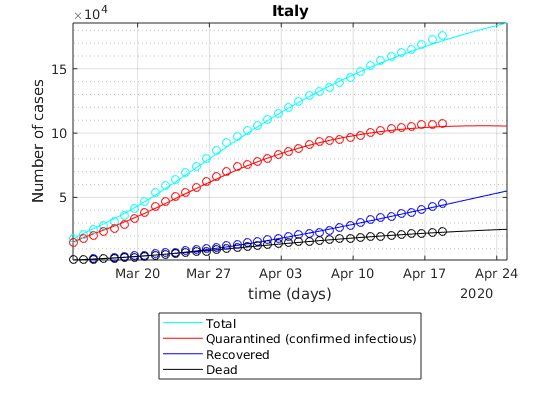

% Merge regional data for each day
tableCOVIDItaly_Tot = varfun(@sum,tableCOVIDItaly, ...
    'InputVariables',tableCOVIDItaly.Properties.VariableNames(7:end), ...
    'GroupingVariables','Date');
% Remove the 'GroupCount' variable, should total to the number of Italian regions (19 + 2 autonomous provinces)
tableCOVIDItaly_Tot = removevars(tableCOVIDItaly_Tot,'GroupCount');
% Rename the accumulated variables with the original variable names
tableCOVIDItaly_Tot.Properties.VariableNames=[tableCOVIDItaly.Properties.VariableNames(1),tableCOVIDItaly.Properties.VariableNames(7:end)];


Npop = 60.48e6; % population

Recovered   = tableCOVIDItaly_Tot.Recovered'  ;
Deaths      = tableCOVIDItaly_Tot.Deaths'     ;
Confirmed   = tableCOVIDItaly_Tot.Confirmed'  ;
Quarantined = tableCOVIDItaly_Tot.Quarantined';
time        = tableCOVIDItaly_Tot.Date'       ;
time = unique(datetime(datestr(datenum(tableCOVIDItaly.Date,'yyyy-mm-DDThh:MM:ss'))));




% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
minNum= round(0.1*max(Confirmed));
Recovered  (Confirmed<=minNum)=[];
Deaths     (Confirmed<=minNum)=[];
time       (Confirmed<=minNum)=[];
Quarantined(Confirmed<=minNum)=[];
Confirmed  (Confirmed<=minNum)=[];


% To simulate the cases after fitting
dt = 1/24; % time step
time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(7)));
N = numel(time1);
t = [0:N-1].*dt;

% Initial conditions
E0 = Confirmed  (1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed  (1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Quarantined(1);
R0 = Recovered  (1);
D0 = Deaths     (1);

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Quarantined,Recovered,Deaths,Npop,E0,I0,time,guess,'Display','off');



[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);


% Comparison of the fitted and real data
figure
semilogy(time1,Q+R+D,'c',time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
set(gca,'ColorOrderIndex',1);
semilogy(time,Confirmed,'co',time,Quarantined,'ro',time,Recovered,'bo',time,Deaths,'ko');
ylabel('Number of cases')
xlabel('time (days)')
title('Italy');
leg = {'Total','Quarantined (confirmed infectious)','Recovered','Dead'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
grid minor
axis tight
set(gca,'yscale','lin')